clear all
close all
load flu
Y = double(flu(:,2:end-1));
[n,d] = size(Y);
x = flu.WtdILI;
figure(1);
regions = flu.Properties.VarNames(2:end-1);
plot(x,Y,'x')
legend(regions,'Location','NorthWest')

%label matrix
r=x; 

**Creation of X Matrix**

% X Matrix
xmat=[ones(1,n)' Y]; 


**Part 1Estimate of W Matrix**

%Genration of W Matrix
W=inv((xmat'*xmat))*xmat'*r;



**Find Equation of Ynew**

%Finding Equation Y 
Ynew= W(1)+ (W(2)*xmat(:,2))+ (W(3)*xmat(:,3)) + (W(4)*xmat(:,4)) +(W(5)*xmat(:,5)) + (W(6)*xmat(:,6)) + (W(7)*xmat(:,7)) + (W(8)*xmat(:,8))+(W(9)*xmat(:,9))+(W(10)*xmat(:,10))

Ynew =     0.9929
    1.1909
    1.4286
    1.7640
    1.7912
    2.0351
    1.5658
    1.9579
    1.7586
    2.0332


**Plotting g(x|Theta) and Label Vector R**

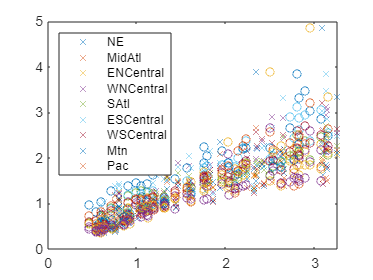

%Plotting g(x|Theta) and Label Vector R
hold on
x = flu.WtdILI;
regions = flu.Properties.VarNames(2:end-1);
plot(Ynew,Y,'o')
legend(regions,'Location','NorthWest')

**Estimate the Error**

%Estimate the difference between calculated and Labeled Outputs
error=Ynew-x

error =    -0.1891
   -0.0291
    0.1186
    0.4210
    0.2052
    0.5651
   -0.0452
    0.1309
   -0.0174
    0.0922
